bag = rosbag('BWBag1.bag')

bag =   BagSelection with properties:

           FilePath: 'C:\Users\TOSHIBA\Desktop\Dortmund\2nd Semester\BW_RV\TestCans\BWBag1.bag'
          StartTime: 1.6631e+09
            EndTime: 1.6631e+09
        NumMessages: 11257
    AvailableTopics: [162×3 table]
    AvailableFrames: {10×1 cell}
        MessageList: [11257×4 table]


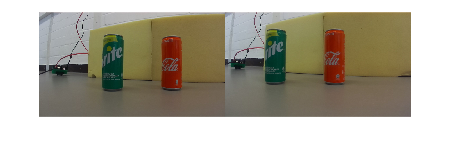


bagselect = select(bag,'Time',...
    [bag.StartTime bag.StartTime + 22],'Topic','zedm/zed_node/stereo_raw/image_raw_color');
msgs = readMessages(bagselect);
i = 8;
%for i = 1:8
    figure
    [imS,alpha] = readImage(msgs{i});
    imshow(imS)

    load zedParameters
    show = dispFlag;
    
    im_size = size(imS);
    imLeft = imS(:,1:im_size(2)/2,:);
    imRight = imS(:,im_size(2)/2+1:im_size(2),:);
    
    [imLeftRect, imRightRect,reprojectionMatrix] = rectifyStereoImages(imLeft, imRight, stereoParams);

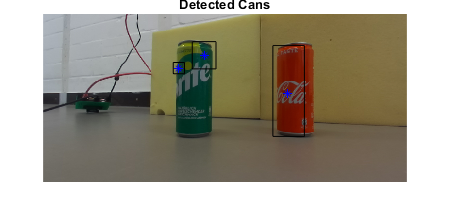

    [bbox_rec, certainty]= colorSegmentation(imLeftRect,dispFlag);

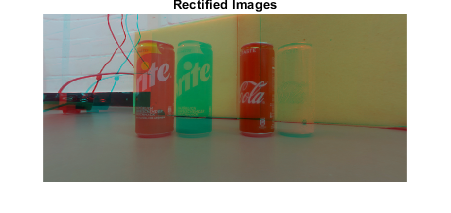

    if(dispFlag)
        figure
        imshow(stereoAnaglyph(imLeftRect, imRightRect))
    
        title('Rectified Images')
    end

P_robot = 3×1 single column vector
   -0.0358
    0.5582
    0.0595


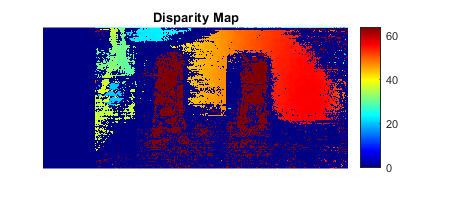

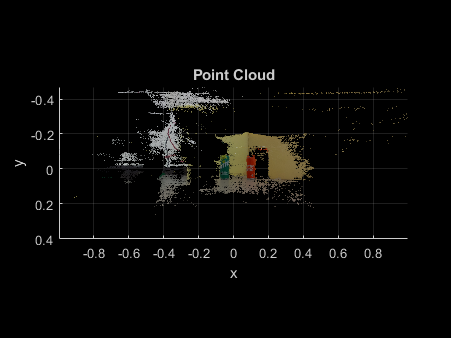

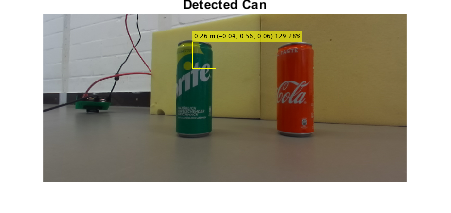

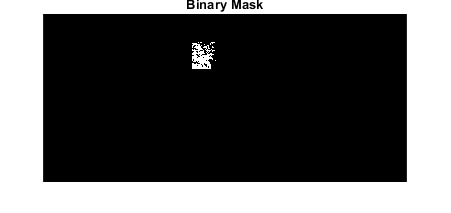

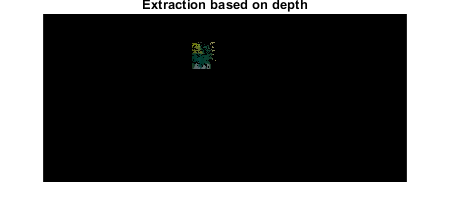

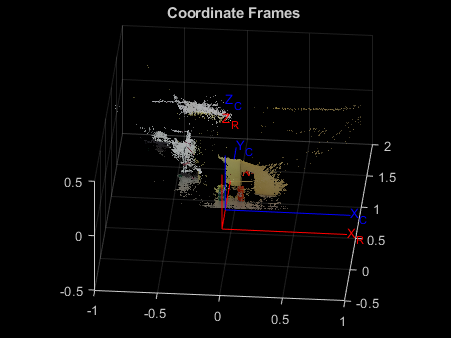

    P_robot = depthEstCans(imLeftRect, imRightRect, reprojectionMatrix, bbox_rec, certainty, show);

    xr = P_robot(1)

xr = single
-0.0358

    yr = P_robot(2)

yr = single
0.2522

    zr = P_robot(3)

zr = single
0.0595

%end % for i=1:10